# Identificazione in presenza di limitazioni di velocità/posizione massima.

Spesso i sistemi meccanici hanno limiti di posizione e velocità massima.

In questo caso, è necessario lavorare con range positivi e negativi.

Tuttavia la presenza dell'attrito statico rende l'approssimazione lineare molto imprecisa quando si lavora con continui cambi di posizione e velocità.

Una soluzione è inserire una "portante", cioè un segnale a bassa frequenza che consente di mantenere la velocità diverse da zero per lunghi tratti.

## Esempio

consideriamo il modello meccanico motore-trasmissione-carico, con trasmissione elastica e presenza di attrito statico.

Il sistema ha un ingresso (la coppia motore), e due uscite (posizione e velocità motore). Ci interessa trovare un modello lineare che approssima la relazione coppia-velocità.

clc;clear all;close all;
set(0, 'defaultFigurePosition',  [ 1440, 792, 2240, 1680]); % figure più grandi
st=1e-3;
model=ElasticTransmission(st);
model.getInputNumber

ans = 1

model.getOutputNumber

ans = 2

cs=ControlledSystem(model);

Definisco la portante come un segnale sinusoidale a bassa frequenza, con un'ampiezza tale da non sforare i limiti. L'ideale è andare in prossimità dei limiti mantenendo un discreto margine (esempio 70% limiti).

omega_portante=0.05;
ampiezza_portante=0.5

ampiezza_portante = 0.5000

T_portante=2*pi/omega_portante;

scelgo una lunghezza dell'esperimento di almeno un periodo della portante.

t=(0:st:(1.1*T_portante))';
portante=ampiezza_portante*sin(omega_portante*t);

Dopo di che posso andare a definire il segnale eccitante, che partirà da una frequenza maggiore (almeno un decade).

w0=omega_portante*30; %rad/s
w1=pi/st; %rad/s
control_action_identificazione = chirp(t,w0/2/pi,t(end),w1/2/pi, 'logarithmic');
ampliezza_identificazione=2;

Sommo i due segnali

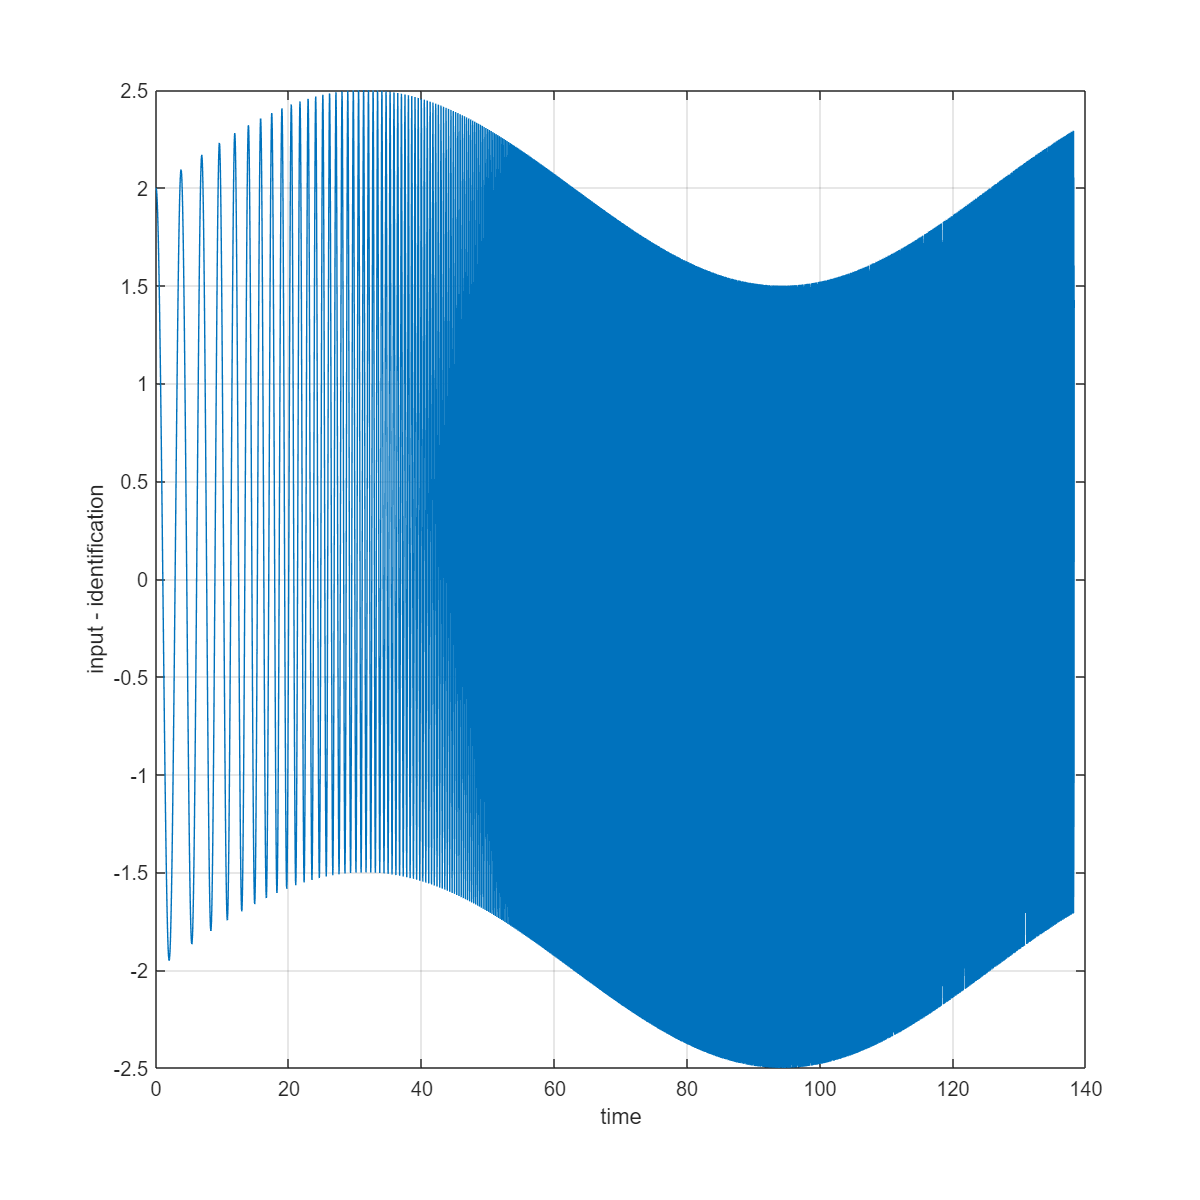

control_action=portante+ control_action_identificazione*ampliezza_identificazione;
figure
plot(t,control_action)
xlabel('time')
ylabel('input - identification')
grid on

## Simulazione sistema

cs.initialize
for idx=1:length(t)
    [process_output(idx,:),t(idx,1)]=cs.openloop(control_action(idx));
end

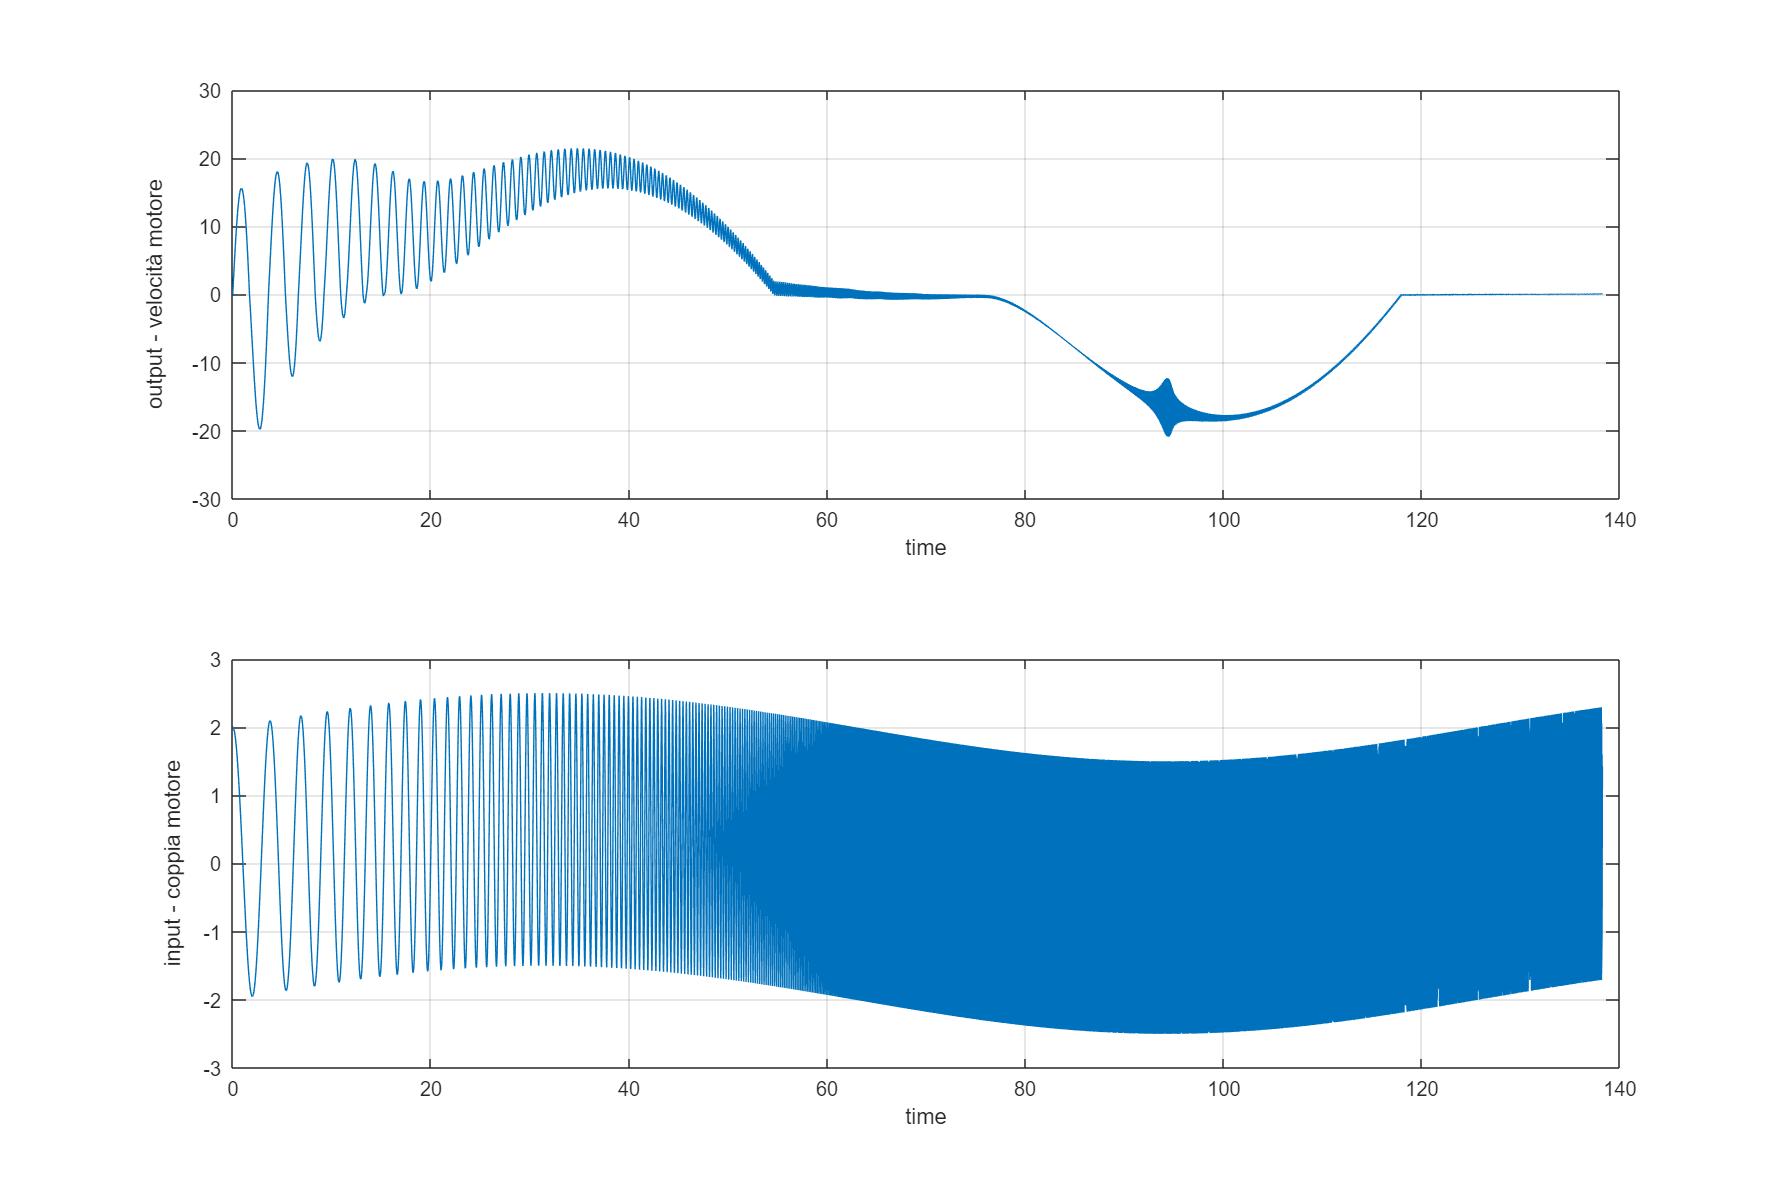


figure(1)
subplot(2,1,1)
plot(t,process_output(:,2))
xlabel('time')
ylabel('output - velocità motore')
grid on

subplot(2,1,2)
plot(t,control_action)
xlabel('time')
ylabel('input - coppia motore')
grid on

## Identificazione

### Calcolo risposta in frequenza

Definisco l'oggetto identification data (iddata)

identification=iddata(process_output(:,2),control_action,st);

Calcolo la risposta in frequenza con il comando e la plotto

freq_resp_ident = spafdr(identification);
figure(2)
bode(freq_resp_ident)

Plotto la frequenza di inizio del segnale eccitante

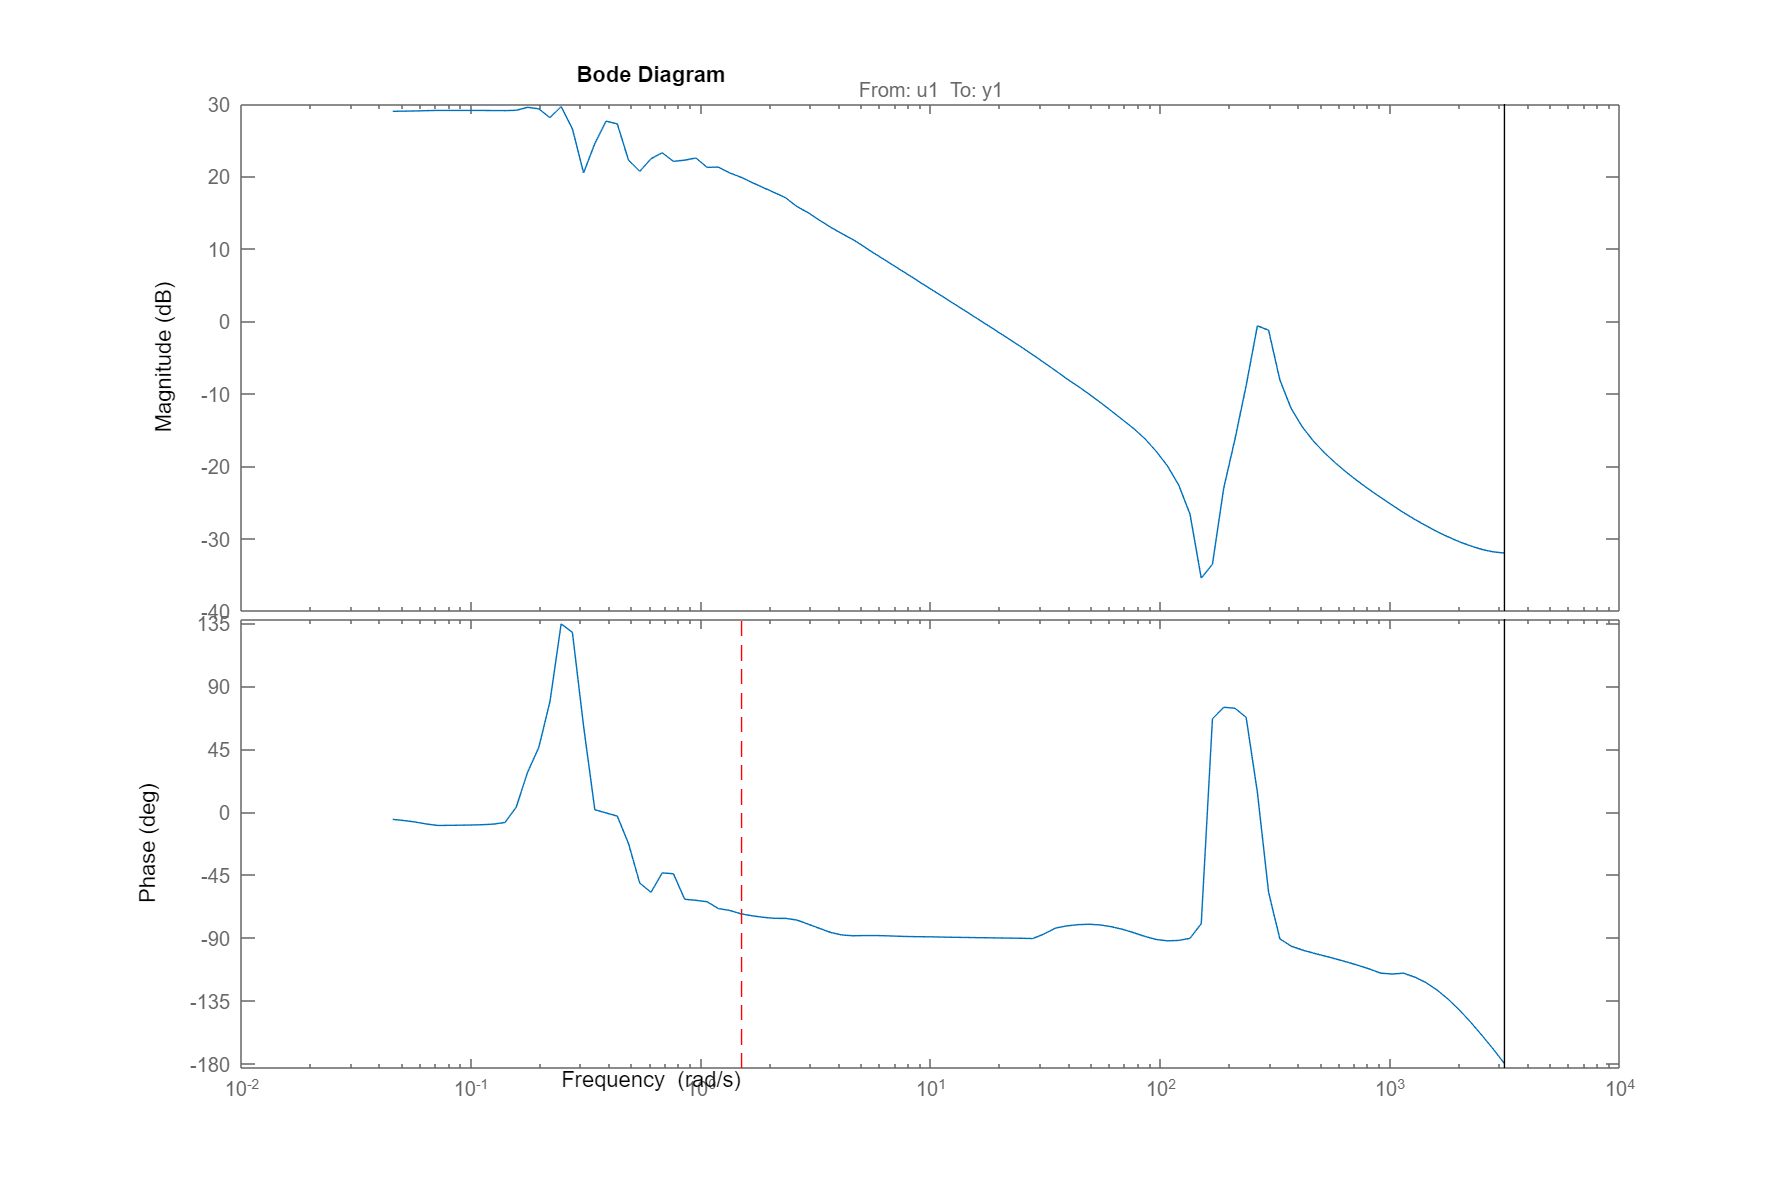

hold on
plot(w0*[1 1],ylim,'--r')
hold off

La parte a sinistra nella linea tratteggiate non mi interessa (il segnale non ha contribuito informatico apprezzabile ed è "disturbato" dalla presenza dell'attrito statico).

### Stima del modello

devo dire al modello di non considerare le basse frequenze. Creo un vettore di pesi da dare allo stimatore (peso basso, poca importanza).

peso=ones(length(freq_resp_ident.Frequency),1);
peso(freq_resp_ident.Frequency<w0)=1e-5;
 
opts=ssestOptions('WeightingFilter',peso,'EnforceStability',1);
modello_continuo = ssest(freq_resp_ident,3,opts);
modello_discreto = ssest(freq_resp_ident,3,'Ts',st,opts);

### Grafico modelli

aggiungo opzione per evitare la molteplicità di 360° nella base

figure(3)
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';

plotto i dati sperimentali

h=bodeplot(freq_resp_ident, bode_opts);

si può aggiungere l'interfavollo di confidenza (in questo caso 3*sigma)

hold on
showConfidence(h,3)

grafico i modelli stimati

bode(modello_continuo,modello_discreto, bode_opts)

visualizzo solo il range di frequenze di interesse

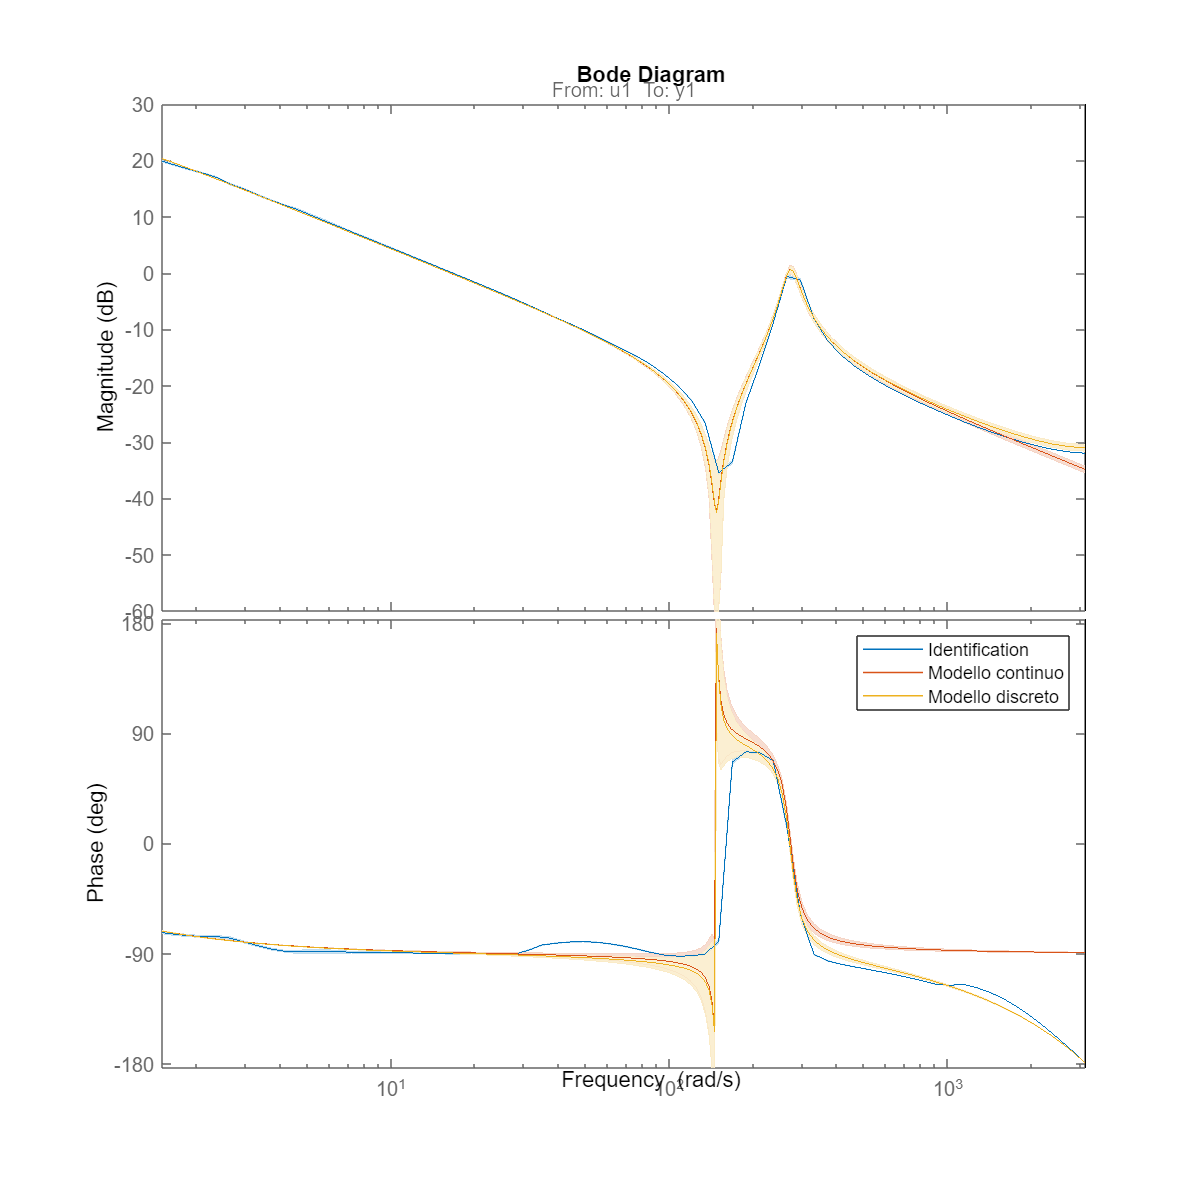

xlim([w0 w1])
hold off

legend('Identification','Modello continuo','Modello discreto')

## Validazione

Cambio portante e segnale eccitante

omega_portante_v=0.03;
ampiezza_portante_v=0.6;
T_portante_v=2*pi/omega_portante_v;

scelgo una lunghezza dell'esperimento di almeno un periodo della portante.

t_v=(0:st:(1.1*T_portante_v))';
portante_v=ampiezza_portante*sin(2*pi/120*t_v);

Dopo di che posso andare a definire il segnale eccitante, che partirà da una frequenza maggiore (almeno un decade).

w0_v=omega_portante_v*30; %rad/s
w1_v=pi/st; %rad/s
control_action_validazione = chirp(t_v,w0_v/2/pi,t_v(end),w1_v/2/pi, 'logarithmic');
ampliezza_validazione=1.5;

Sommo i due segnali

control_action_v=portante_v+ control_action_validazione*ampliezza_validazione;

cs.initialize

for idx=1:length(t_v)
    [process_output_v(idx,:),t_v(idx,1)]=cs.openloop(control_action_v(idx));
end

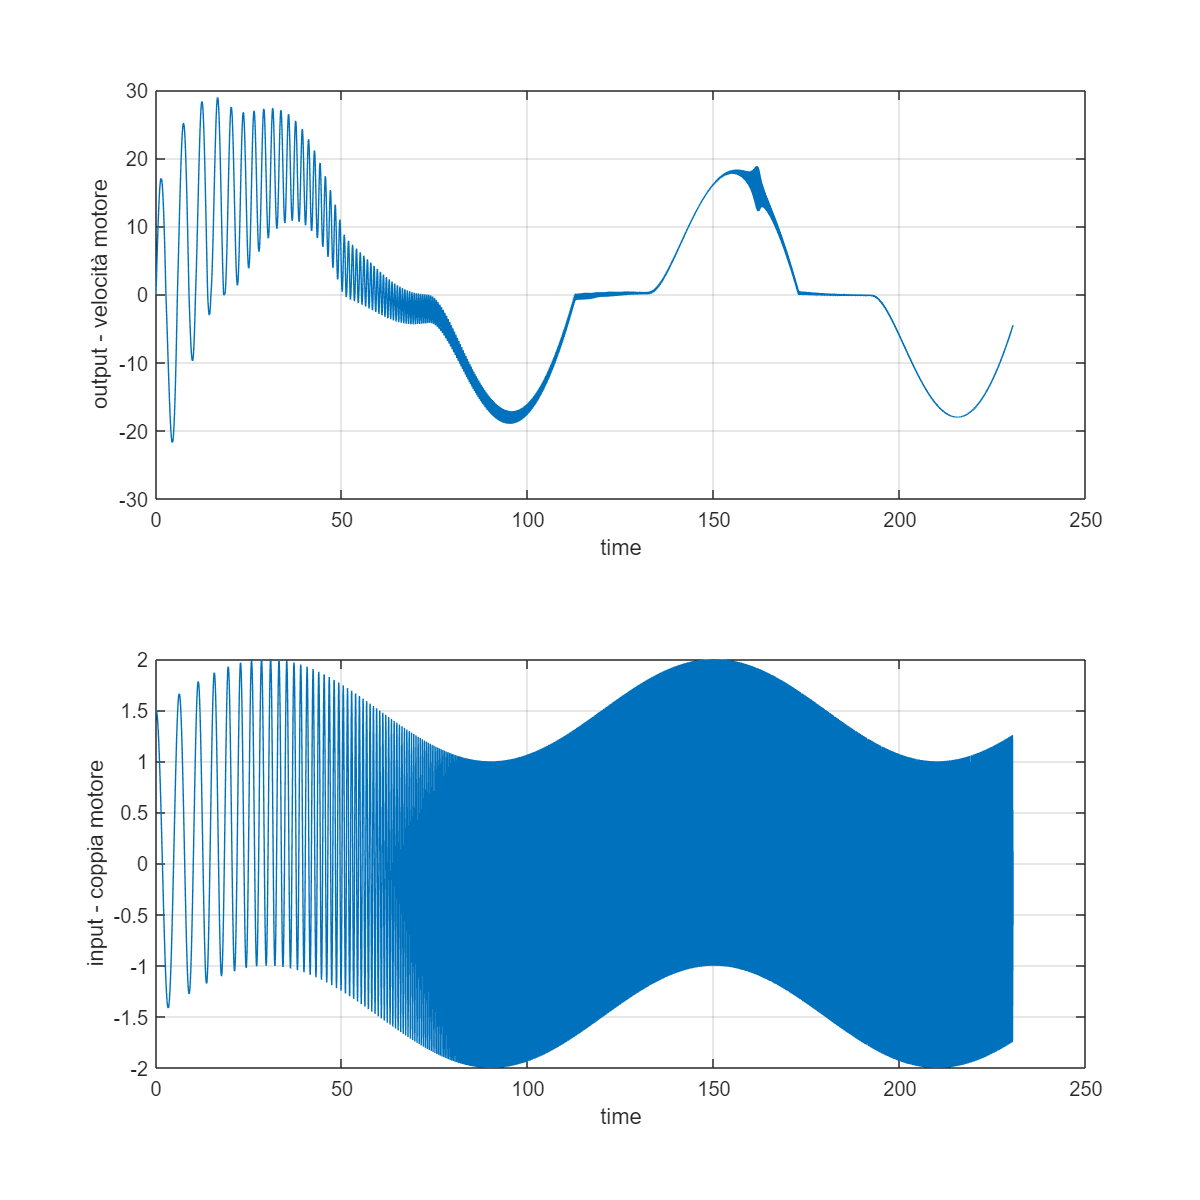

figure(4)
subplot(2,1,1)
plot(t_v,process_output_v(:,2))
xlabel('time')
ylabel('output - velocità motore')
grid on

subplot(2,1,2)
plot(t_v,control_action_v)
xlabel('time')
ylabel('input - coppia motore')
grid on

### Validazione in frequenza

validation=iddata(process_output_v(:,2),control_action_v,st);
freq_resp_vali = spafdr(validation);
figure(5)
bode(freq_resp_vali,freq_resp_ident,bode_opts)

Plotto la frequenza di inizio del segnale eccitante

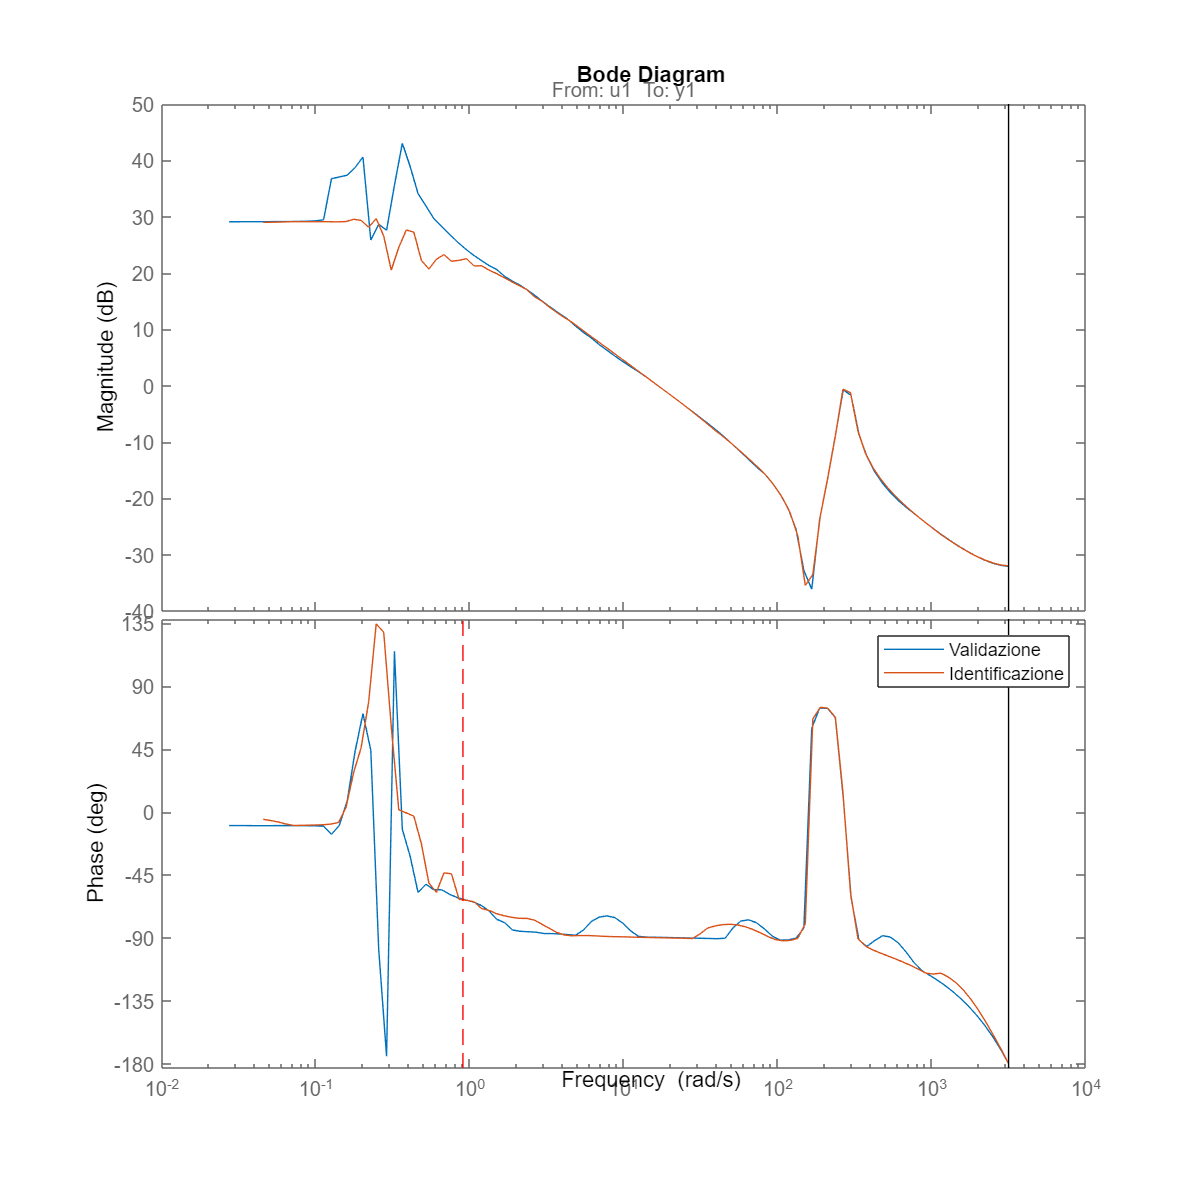

hold on
plot(w0_v*[1 1],ylim,'--r')
hold off
legend('Validazione','Identificazione')

Grafico diagrammi di Bode

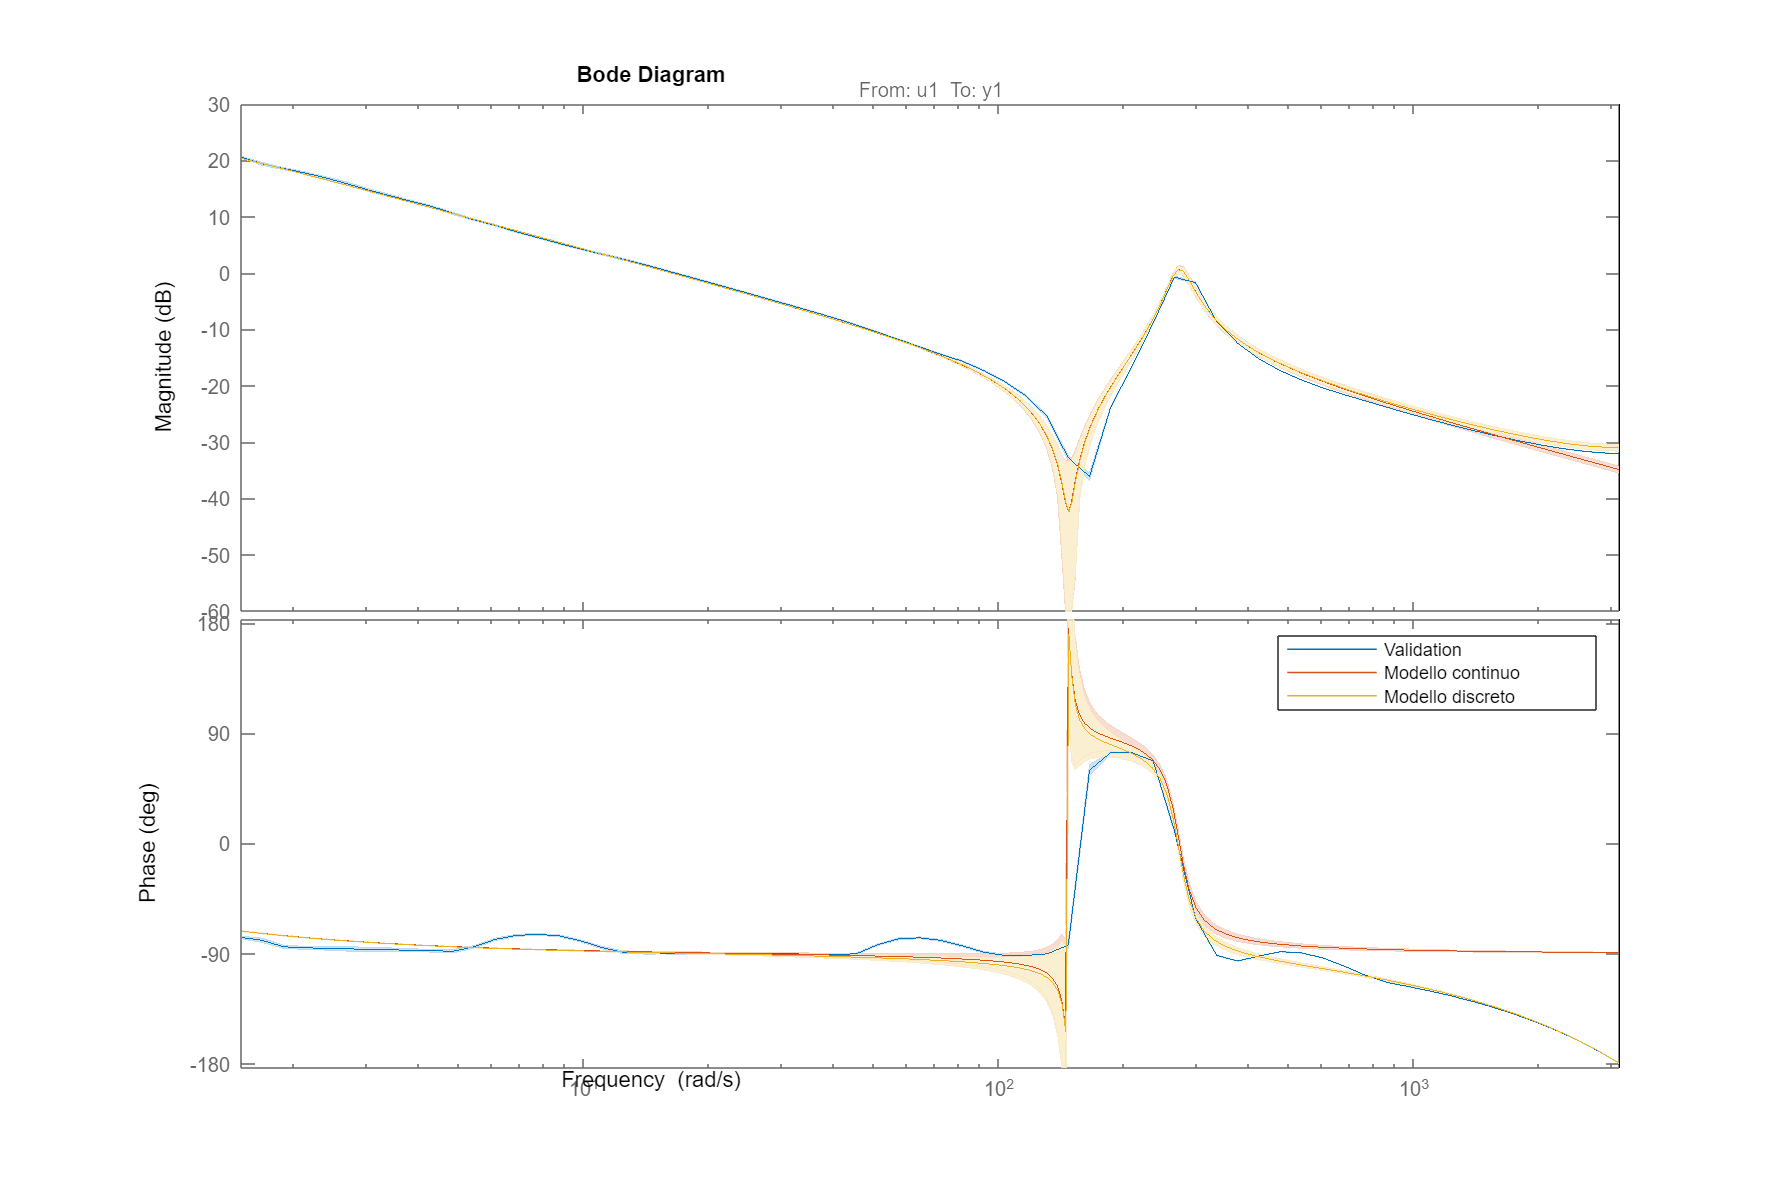

figure(6)
h=bodeplot(freq_resp_vali, bode_opts);
hold on
showConfidence(h,3)
bode(modello_continuo,modello_discreto, bode_opts)
xlim([w0 w1])
hold off

legend('Validation','Modello continuo','Modello discreto')